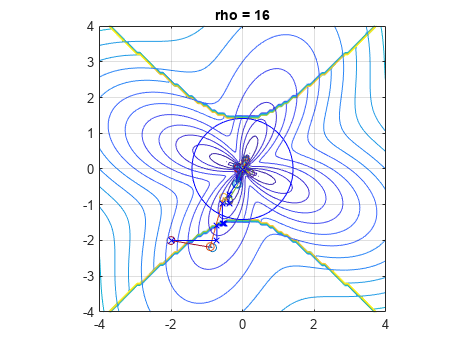

clear;clc;clf;
%% flower

func = @(x) flower(x);
func_grad = @(x) flower_grad(x);

constr = @(x) x(1)^2 -x(2)^2 + 2;
constr_grad = @(x) [-2*x(1), -2*x(2)];

penalty_quad = @(x) max(constr(x),0)^2;
penalty_quad_grad = @(x) 2*max(constr(x),0).*constr_grad(x);
penalty_count = @(x) (constr(x) > 0);

x0 = [-2; -2];

xs = linspace(-4,4); ys = linspace(-4,4); [Xs,Ys] = meshgrid(xs,ys);
for i=1:100
    for j=1:100
        Zs(i,j) = func([Xs(i,j),Ys(i,j)]);
    end
end
contour(Xs,Ys,Zs); hold on; grid on; axis equal; plot3(0,0,0,'ko');

cyclic_p(func, penalty_count, x0)
% de_pen(func, penalty_count, x0)
% bfgs_aug_lagr(func, func_grad, constr, penalty_quad, penalty_quad_grad, x0)
% bfgs_quad_pen(func, func_grad, penalty_quad, penalty_quad_grad, x0)

function [val] = flower(x)
a = 1; b = 1; c = 4;
val = a*norm(x) + b*sin(c*atan2(x(2),x(1)));
end

function [val] = flower_grad(x)
a = 1; b = 1; c = 4;
val = [a*x(1)/norm(x) + b*cos(c*atan2(x(2),x(1)))*(-c*x(2))/(norm(x)^2);
       a*x(2)/norm(x) + b*cos(c*atan2(x(2),x(1)))*(c*x(1))/(norm(x)^2)];
end

function [val] = cyclic_p(func, penalty_count, x0)
%% cyclic serach with penalisation
for rho= [0.5,1,5,10]
    f = @(x) func(x)+ rho*penalty_count(x);
    xs = linspace(-4,4); ys = linspace(-4,4); [Xs,Ys] = meshgrid(xs,ys);
    for i=1:100
        for j=1:100
            Zs(i,j) = f([Xs(i,j),Ys(i,j)]);
        end
    end
    contour(Xs,Ys,Zs); hold on; grid on; axis equal; plot3(0,0,0,'ko');
    
    title(['rho = ',num2str(rho)]);
    t = linspace(0,2*pi);
    xs_circ = sqrt(2)*sin(t); ys_circ =  sqrt(2)*cos(t); 
    plot3(xs_circ(:), ys_circ(:), zeros(1,100),'b-');

    xs = [x0]; plot3(xs(1,end), xs(2,end), f(xs(:,end)),'rx')
    delta = inf; n = 2; iter = 1;
    while abs(delta) > 1e-4
        x_1 = xs(:, iter); x = x_1;
        for i = 1:n
            d = zeros(n,1); d(i)=1;
            f_red = @(alpha) f(x+d*alpha);
            [a,c] = bracket_minimum(f_red, 0);
            [a,b] = golden_section_search(f_red,a,c,50);
            alpha = (a+b)/2;
            x = x + alpha*d;
            xs(:, end+1) = x;
            iter = iter+1;
            plot3([xs(1,end-1),xs(1,end)],[xs(2,end-1),xs(2,end)],[f(xs(:,end-1)), f(xs(:,end))],'b-x'); pause(0.1)
        end
            d = x-x_1;
            f_red = @(alpha) f(x+d*alpha);
            [a,c] = bracket_minimum(f_red, 0);
            [a,b] = golden_section_search(f_red,a,c,50);
            alpha = (a+b)/2;
            x = x + alpha*d;
            xs(:, end+1) = x;
            iter = iter+1;
            plot3([xs(1,end-1),xs(1,end)],[xs(2,end-1),xs(2,end)],[f(xs(:,end-1)), f(xs(:,end))],'b-x'); 
            delta = norm(x-x_1);
            if iter > 100
                break;
            end
    end
    x0 = xs(:,end);
end
hold on
f = @(x) flower(x);
xs_plot = linspace(-4,4); ys_plot = linspace(-4,4); [Xs,Ys] = meshgrid(xs_plot,ys_plot);
for i=1:100
    for j=1:100
        Zs(i,j) = f([Xs(i,j),Ys(i,j)]);
    end
end
contour(Xs,Ys,Zs); hold on; grid on; axis equal; plot3(0,0,0,'ko');
x_end = xs(:,end);
val_end = f(xs(:,end));
plot3(x_end(1),x_end(2),0,'kx','LineWidth',2,'MarkerSize',10);
end

function [val] = de_pen(func, penalty_count, x0)
%% de with count penalty
rho= 10;
f = @(x) func(x)+ rho*penalty_count(x);
xs = linspace(-4,4); ys = linspace(-4,4); [Xs,Ys] = meshgrid(xs,ys);
for i=1:100
    for j=1:100
        Zs(i,j) = f([Xs(i,j),Ys(i,j)]);
    end
end
contour(Xs,Ys,Zs); hold on; grid on; axis equal; plot3(0,0,0,'ko');
title(['rho = ',num2str(rho)]);
t = linspace(0,2*pi);
xs_circ = sqrt(2)*sin(t); ys_circ =  sqrt(2)*cos(t); 
plot3(xs_circ(:), ys_circ(:), zeros(1,100),'b-');

xs = [x0]; plot3(xs(1,end), xs(2,end), f(xs(:,end)),'rx'); pause(0.1);
m = 8;n = 2; pop = [x0+randn(n,m)]; 
k_max = 100; w = 0.8; p = 0.9;
for i=1:m
    val(i) = f(pop(:,i));
end
for k=1:k_max
    pop_plot = plot3(pop(1,:),pop(2,:),zeros(1,m),'rx','LineWidth',2);
    children = zeros(2,m);
    for i=1:m
        perm = randperm(m,3);
        z = pop(:,perm(1)) + w*(pop(:,perm(2)) - pop(:,perm(3)));
        j = randperm(n,1);
        children(:,i) = pop(:,i);
        for d = 1:n
            if d == j || p < rand(1)
                children(d,i) = z(d);
            end
        end
    end
    for i=1:m
        val_child = f(children(:,i));
        if val_child < val(i)
            pop(:,i) = children(:,i);
            val(i) = val_child;
        end
    end
    pause(0.01);
    pop_plot.Visible = 'off';
end
pop_plot = plot3(pop(1,:),pop(2,:),zeros(1,m),'rx','LineWidth',2); min(val)
pop_plot = plot3(pop(1,:),pop(2,:),zeros(1,m),'rx','LineWidth',2,'MarkerSize',10);
hold on

f = @(x) flower(x);
xs_plot = linspace(-4,4); ys_plot = linspace(-4,4); [Xs,Ys] = meshgrid(xs_plot,ys_plot);
for i=1:100
    for j=1:100
        Zs(i,j) = f([Xs(i,j),Ys(i,j)]);
    end
end
contour(Xs,Ys,Zs, 0:50); hold on; grid on; axis equal; plot3(0,0,0,'ko');
x_end = xs(:,end);
val_end = f(xs(:,end));
plot3(x_end(1),x_end(2),0,'kx','LineWidth',2,'MarkerSize',10);

end

function [val] = bfgs_aug_lagr(func, func_grad, constr, penalty_quad, penalty_quad_grad, x0)
%% BFGS Quasi-Newton with augmenterd lagrange
xs = x0; epsilon = 1e-6; delta = inf; lambda = 0; iter_max = 30;
g = func_grad(xs); Q = eye(2);

for rho = [0.01, 0.5, 1, 4, 8, 16]
    
    title(['rho = ',num2str(rho)]);
    t = linspace(0,2*pi);
    xs_circ = sqrt(2)*sin(t); ys_circ =  sqrt(2)*cos(t); 
    plot3(xs_circ(:), ys_circ(:), zeros(1,100),'b-'); iter = 1;

    while delta > epsilon
        d = -Q*g;
    
        f = @(x) func(x) + rho*penalty_quad(x);
        f_red = @(alpha) f(xs(:,end) + d*alpha);
        
        [a,c] = bracket_minimum(f_red);
        [a,b] = golden_section_search(f_red,a,c,50);
        alpha = (a+b)/2;
        
        xs(:,end + 1) = xs(:,end) + alpha*d;
        plot3([xs(1,end), xs(1,end-1)], [xs(2,end), xs(2,end-1)],[0,0],'-o');pause(0.1)
        
        g_old = g;
        grad = @(x) func_grad(x) + (rho*penalty_quad_grad(x))';
        g = grad(xs(:,end));
        
        gamma = g - g_old;
        delta = norm(xs(:,end) -  xs(:,end-1));
        
        Q = Q - (Q*gamma)*(gamma'*Q)/(gamma'*Q*gamma) + delta*delta'./delta'*gamma;
        lambda = lambda - rho*constr(xs(:,end));
        iter = iter +1;
        if iter > 20
            break
        end
    xs = xs(:,end);
    end
    hold on
    f = @(x) flower(x);
    xs_plot = linspace(-4,4); ys_plot = linspace(-4,4); [Xs,Ys] = meshgrid(xs_plot,ys_plot);
    for i=1:100
        for j=1:100
            Zs(i,j) = f([Xs(i,j),Ys(i,j)]);
        end
    end
    contour(Xs,Ys,Zs); hold on; grid on; axis equal; plot3(0,0,0,'ko');
    x_end = xs(:,end);
    val_end = f(xs(:,end));
    plot3(x_end(1),x_end(2),0,'kx','LineWidth',2,'MarkerSize',10);
end
end

function [val] = bfgs_quad_pen(func, func_grad, penalty_quad, penalty_quad_grad, x0)
%% BFGS Quasi-Newton with with quadratic penaliyation

xs = x0;
epsilon = 1e-6; delta = inf;

g = func_grad(xs); Q = eye(2);

for rho = [0.01, 0.5, 1, 4, 8, 16]
    title(['rho = ',num2str(rho)]);
    t = linspace(0,2*pi);
    xs_circ = sqrt(2)*sin(t); ys_circ =  sqrt(2)*cos(t); 
    plot3(xs_circ(:), ys_circ(:), zeros(1,100),'b-'); iter = 1;

    while delta > epsilon
        d = -Q*g;
    
        f = @(x) func(x) + rho*penalty_quad(x);
        f_red = @(alpha) func(xs(:,end) + d*alpha);
     
        [a,c] = bracket_minimum(f_red);
        [a,b] = golden_section_search(f_red,a,c,50);
        alpha = (a+b)/2;
        xs(:,end + 1) = xs(:,end) + alpha*d;
        plot3([xs(1,end), xs(1,end-1)], [xs(2,end), xs(2,end-1)],[0,0],'-o');pause(0.1)
        g_old = g;
        grad = @(x) func_grad(x) + (rho*penalty_quad_grad(x))';
        g = grad(xs(:,end));
        gamma = g - g_old;
        delta = norm(xs(:,end) -  xs(:,end-1));
        Q = Q - (Q*gamma)*(gamma'*Q)/(gamma'*Q*gamma) + delta*delta'./delta'*gamma;
    
        iter = iter +1;
        if iter > 100
            break
        end
    end
xs = xs(:,end);
end
    hold on
    f = @(x) flower(x);
    xs_plot = linspace(-4,4); ys_plot = linspace(-4,4); [Xs,Ys] = meshgrid(xs_plot,ys_plot);
    for i=1:100
        for j=1:100
            Zs(i,j) = f([Xs(i,j),Ys(i,j)]);
        end
    end
    contour(Xs,Ys,Zs); hold on; grid on; axis equal; plot3(0,0,0,'ko');
    x_end = xs(:,end);
    val_end = f(xs(:,end));
    plot3(x_end(1),x_end(2),0,'kx','LineWidth',2,'MarkerSize',10);
end

function [a,c] = bracket_minimum(f,varargin)

switch length(varargin)
    case 0 
        x = 0; s = 1e-2; k = 2;
    case 1
        x = varargin{1}; s = 1e-2; k = 2;
    case 2
        x = varargin{1}; s = varargin{2}; k = 2;
    case 3
        x = varargin{1}; s = varargin{2}; k = varargin{3};
    otherwise
        disp("TOO MANY INPUTS")
        a = 0; c = 0; return;
end

a = x; ya = f(x); 
b = a+s; yb = f(a+s);

if yb>ya
    temp = a; a = b; b = temp;
    temp = ya; ya = yb; yb = temp;
    s = -s;
end

while true
    c = b+ s; yc = f(b+s);
    if yc > yb
        if a < c
            return
        else
            temp = a; a = c; c = temp; 
            return
        end
    end
    a = b; ya = yb; b = c; yb = yc;
    s = k*s;
end

end 

function [a,b] = golden_section_search(f,a,b,n)
fi = (1+sqrt(5))/2;
rho = fi - 1;
d = rho*b + (1-rho)*a;
yd = f(d);
for i=1:n-1
   c = rho*a+(1-rho) *b;
   yc = f(c);
   if yc < yd 
      b = d; d = c; yd = yc;
   else
       a = b; b = c;
   end   
end

if a < b
   return
else
    temp = a; a = b; b = temp; 
end

end
